**Nonlinear Support Vector Machine**

Consider the training data given. Find the nonlinear regression function given by the nonlinear SVM using a polynomial kernel with degree p = 3 and parameters ε = 10, C = 10. Moreover, find the support vectors

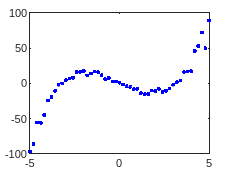

close all;
clear;
clc; 

matlab.lang.OnOffSwitchState = 1;

data = [-5.0000  -96.2607 
   -4.8000  -85.9893
   -4.6000  -55.2451
   -4.4000  -55.6153
   -4.2000  -44.8827
   -4.0000  -24.1306
   -3.8000  -19.4970
   -3.6000  -10.3972
   -3.4000   -2.2633
   -3.2000    0.2196
   -3.0000    4.5852
   -2.8000    7.1974
   -2.6000    8.2207
   -2.4000   16.0614
   -2.2000   16.4224
   -2.0000   17.5381
   -1.8000   11.4895
   -1.6000   14.1065
   -1.4000   16.8220
   -1.2000   16.1584
   -1.0000   11.6846
   -0.8000    5.9991
   -0.6000    7.8277
   -0.4000    2.8236
   -0.2000    2.7129
         0    1.1669
    0.2000   -1.4223
    0.4000   -3.8489
    0.6000   -4.7101
    0.8000   -8.1538
    1.0000   -7.3364
    1.2000  -13.6464
    1.4000  -15.2607
    1.6000  -14.8747
    1.8000   -9.9271
    2.0000  -10.5022
    2.2000   -7.7297
    2.4000  -11.7859
    2.6000  -10.2662
    2.8000   -7.1364
    3.0000   -2.1166
    3.2000    1.9428
    3.4000    4.0905
    3.6000   16.3151
    3.8000   16.9854
    4.0000   17.6418
    4.2000   46.3117
    4.4000   53.2609
    4.6000   72.3538
    4.8000   49.9166
    5.0000   89.1652];

x = data(:,1) ;
y = data(:,2) ;
l = length(x) ; % number of points

plot(x,y, 'b.');

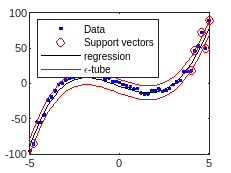

%% nonlinear regression - dual problem

epsilon = 10 ;
C = 10;

% define the problem
X = zeros(l,l);
for i = 1 : l
    for j = 1 : l
        X(i,j) = kernel(x(i),x(j)) ;
    end
end
Q = [ X -X ; -X X ];   
c = epsilon*ones(2*l,1) + [-y;y]; 

% solve the problem
options = optimset('Display', 'off');
solution = quadprog(Q,c,[],[],...
    [ones(1,l) -ones(1,l)],0,...
    zeros(2*l,1),C*ones(2*l,1), [], options);
lap = solution(1:l);
lam = solution(l+1:2*l);

% compute b
ind = find(lap > 1e-3 & lap < C-1e-3);
if ~isempty(ind)
    i = ind(1);
    b = y(i) - epsilon;
    for j = 1 : l
        b = b - (lap(j)-lam(j))*kernel(x(i),x(j));
    end
else
    ind = find(lam > 1e-3 & lam < C-1e-3);
    i = ind(1);
    b = y(i) + epsilon ;
    for j = 1 : l
        b = b - (lap(j)-lam(j))*kernel(x(i),x(j));
    end
end

% find regression and epsilon-tube
z = zeros(l,1);
for i = 1 : l
    z(i) = b ;
    for j = 1 : l
        z(i) = z(i) + (lap(j)-lam(j))*kernel(x(i),x(j));
    end
end
zp = z + epsilon ;
zm = z - epsilon ;

%% plot the solution

% find support vectors
sv = [find(lap > 1e-3);find(lam > 1e-3)]; 
sv = sort(sv);

plot(x,y,'b.',x(sv),y(sv),...
    'ro',x,z,'k-',x,zp,'r-',x,zm,'r-');

legend('Data','Support vectors',...
    'regression','\epsilon-tube',...
    'Location','NorthWest')

function v = kernel(x,y)
    %% kernel function
    p = 4 ;
    v = (x'*y + 1)^p;
end